# Frequency Response · 학습

## 실행 조건

MATLAB · Control System Toolbox

## 이번에 배울 내용

주파수마다 입력의 진폭과 위상이 어떻게 변하는지 알면 Bode plot을 실제 신호와 연결할 수 있습니다.

## 전체 흐름

정현파 입력 → Steady State 출력 → 진폭비·위상 → Bode plot

## 정현파를 넣고 Steady State만 읽기

선형 시스템에 sin(ωt)를 넣으면 안정한 Steady State에서는 같은 주파수의 정현파가 나옵니다. 진폭의 비가 |G(jω)|, 입력에 대한 이동이 위상입니다.

시작 직후의 Transient Response는 추정에서 제외해야 합니다.

## Bode plot의 단위

Gain의 dB 표시는 20log10(진폭비)입니다. 위상은 degree 또는 radian인지 확인합니다. 1 Hz는 2π rad/s이므로 숫자 1을 그대로 대입하면 다른 실험이 됩니다.

공진 부근에서는 주파수를 조금 바꿔도 응답이 크게 달라질 수 있습니다.

## 정현파와 위상 지연

$G(s)=\frac1{s+1}$에 sin(t)를 입력합니다. $\omega=1$ rad/s에서 진폭비는 1/√2, 위상은 −45°입니다.

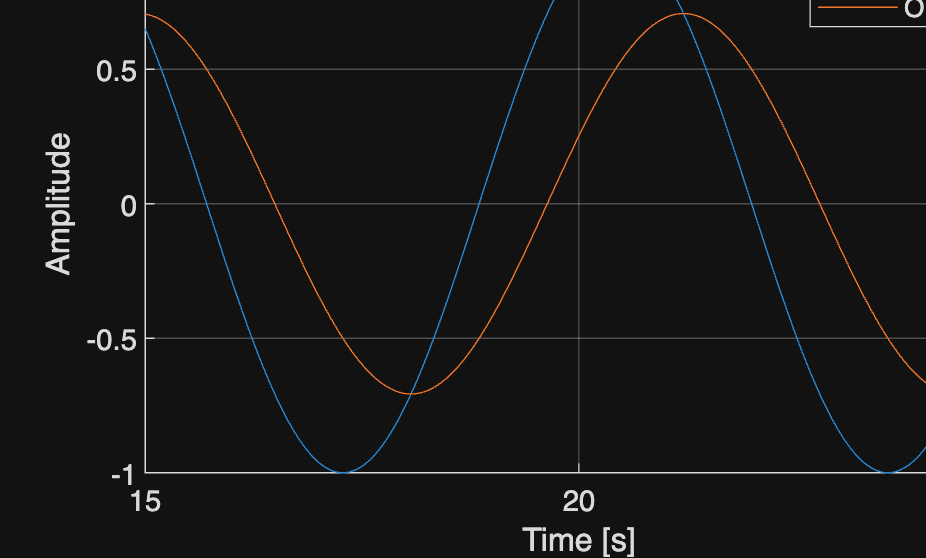

%% Worked example
s=tf('s'); G=1/(s+1); t=linspace(0,25,2501)'; u=sin(t);
y=lsim(G,u,t); figure; plot(t,u,t,y); xlim([15 25]);
xlabel('Time [s]'); ylabel('Amplitude'); legend('Input','Output'); grid on

z=evalfr(G,1i); fprintf('Magnitude %.9g, Phase [deg] %.9g\n',abs(z),rad2deg(angle(z)));

Magnitude 0.707106781, Phase [deg] -45


## 참고 예제

추가 예제 보기

[참고 자료](https://chorok-daddy.github.io/niil/ko/courses/control-2/frequency-response/index.html)